# Creating Loops

### Musical Notes and Frequencies

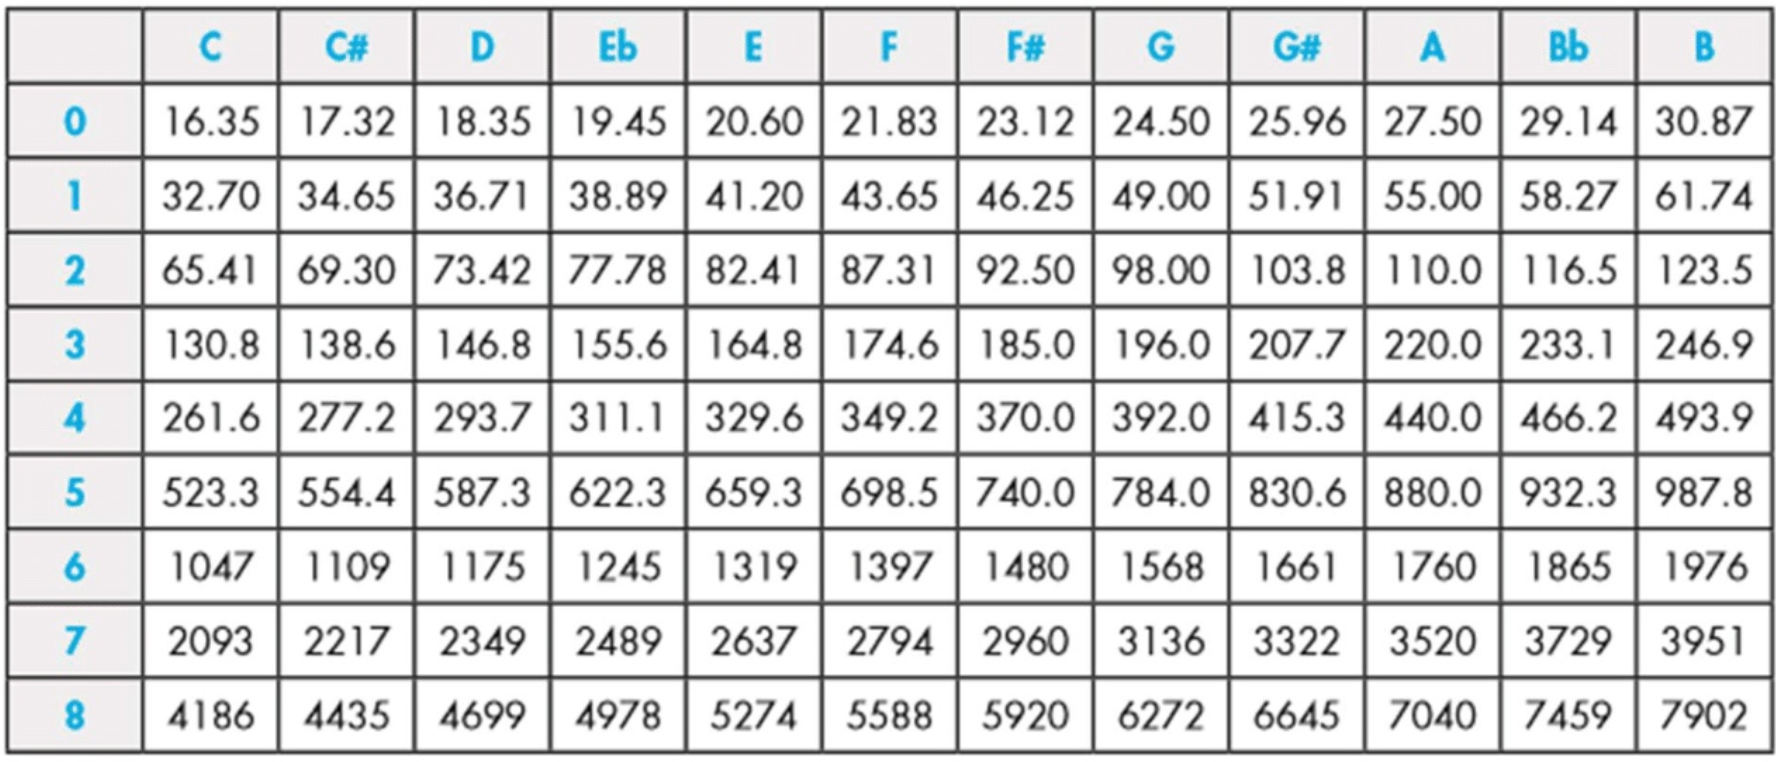

### Practice Loops

for i=1:6
    disp(i)
end
disp("Loop ended")

### Create variables to store frequencies

G4 = 
A4 = 
C5 = 
B4 = 
D5 = 
G5 = 
F5 = 
E5 = 

### Create vectors of tone frequencies and durations

freq = [  ];
t_dur=[  ];

### Use 'for' loop to play the tune

for 



end


**Helper Functions **(do not edit)

function varargout = sineSound(varargin)

    Fs = 8000; 
    Ts = 1/Fs;
    
if nargin == 1
    freq = round(varargin{1},3);
    time = 0.2 ; 
    amp = 1;
    
elseif nargin == 2
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = 1;
    
elseif nargin == 3
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = varargin{3};
   
end

t = 0:Ts:time;
pure_sine = sin(2*pi*freq*t); 
step = 1/(length(t)/2); 
len = 1;
sine_coefficient = [(sin((pi* [0:step:len/2.0]) / (len))) ...
                        ones(1, length([len/2.0:step:len*3/2]) - 2)...
                        abs(sin((pi* [len*3/2:step:len*2.0]) / (len)))]; %#ok<*NBRAK>

env = 0.5*amp.*pure_sine.*sine_coefficient;


if nargout == 1
    varargout{1} = env';
else 
    sound(env, Fs);
end
end

© COPYRIGHT 2024 by The MathWorks®, Inc.